## Lab 6: Controller Design Using Root Locus - Solution

### Instruction

For executing code, you can select the code and Press F9 (or right click and select **Evaluate Selection in Command Window**).

### Design Criteria

Less than 5% overshoot and 1 second rise time.

### Plotting the Root Locus of a Transfer Function

%% Thoery
s = tf('s');
sys = (s + 7)/(s*(s + 5)*(s + 15)*(s + 20));
rlocus(sys)
axis([-22 3 -15 15])


### Choosing a Value of K from the Root Locus

%% Choosing a value of K
zeta = 0.7; % calculate using lab 4 equation 11
wn = 1.8; % calculate using lab 4 equation 10
sgrid(zeta,wn)

Select a point in between two dotted lines at about 45-degree angles (where zeta>0.7) and outside semicircle (where wn>1.8).

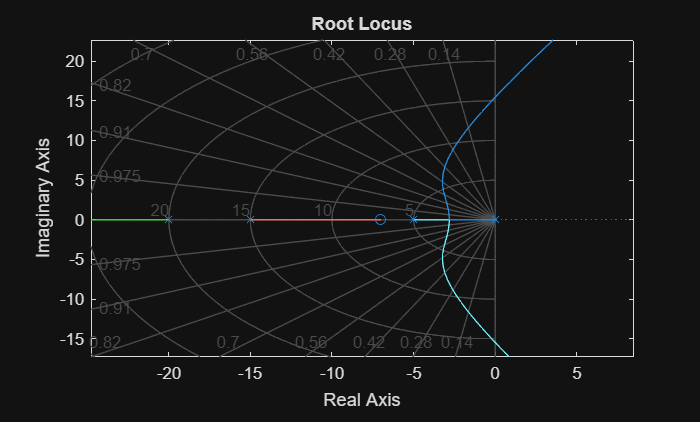

%% Selecting a value of K
[k,poles]=rlocfind(sys)

### Closed-Loop Response

%% closed-loop response
K = 350;
sys_cl = feedback(K*sys,1)

### Step Response

%% Step response

step(sys_cl)

### Using Control System Designer for Root Locus Design

%% Using Control System Designer
s = tf('s');
plant = (s + 7)/(s*(s + 5)*(s + 15)*(s + 20));
controlSystemDesigner(plant)

Add design requirements to the Root Locus plot. Zoom into the Root Locus plot.

Add design requirements of Peak Response and Rise Time.

### Task 1

%% Task 1
% Parameters
J = 0.01;
b = 0.1;
K = 0.01;
R = 1;
L = 0.5;

s = tf('s');
P_motor = K/((J*s + b)*(L*s + R) + K^2);
%linearSystemAnalyzer('step', P_motor, 0:0.1:5);

% Control Requirement
% Settling time < 2s, ts = 4.6 / (zeta * wn)
% Overshoot less than 5%, mp = exp(-(zeta * pi)/(sqrt(1-zeta^2)))
% Steady-state error < 1%
% Hold the pole location to find poles values, zeta, wn

controlSystemDesigner(P_motor)

In the Control System Designer, right click on the `Step Response` figure and select `Settling Time` and `Steady State` Characteristics.

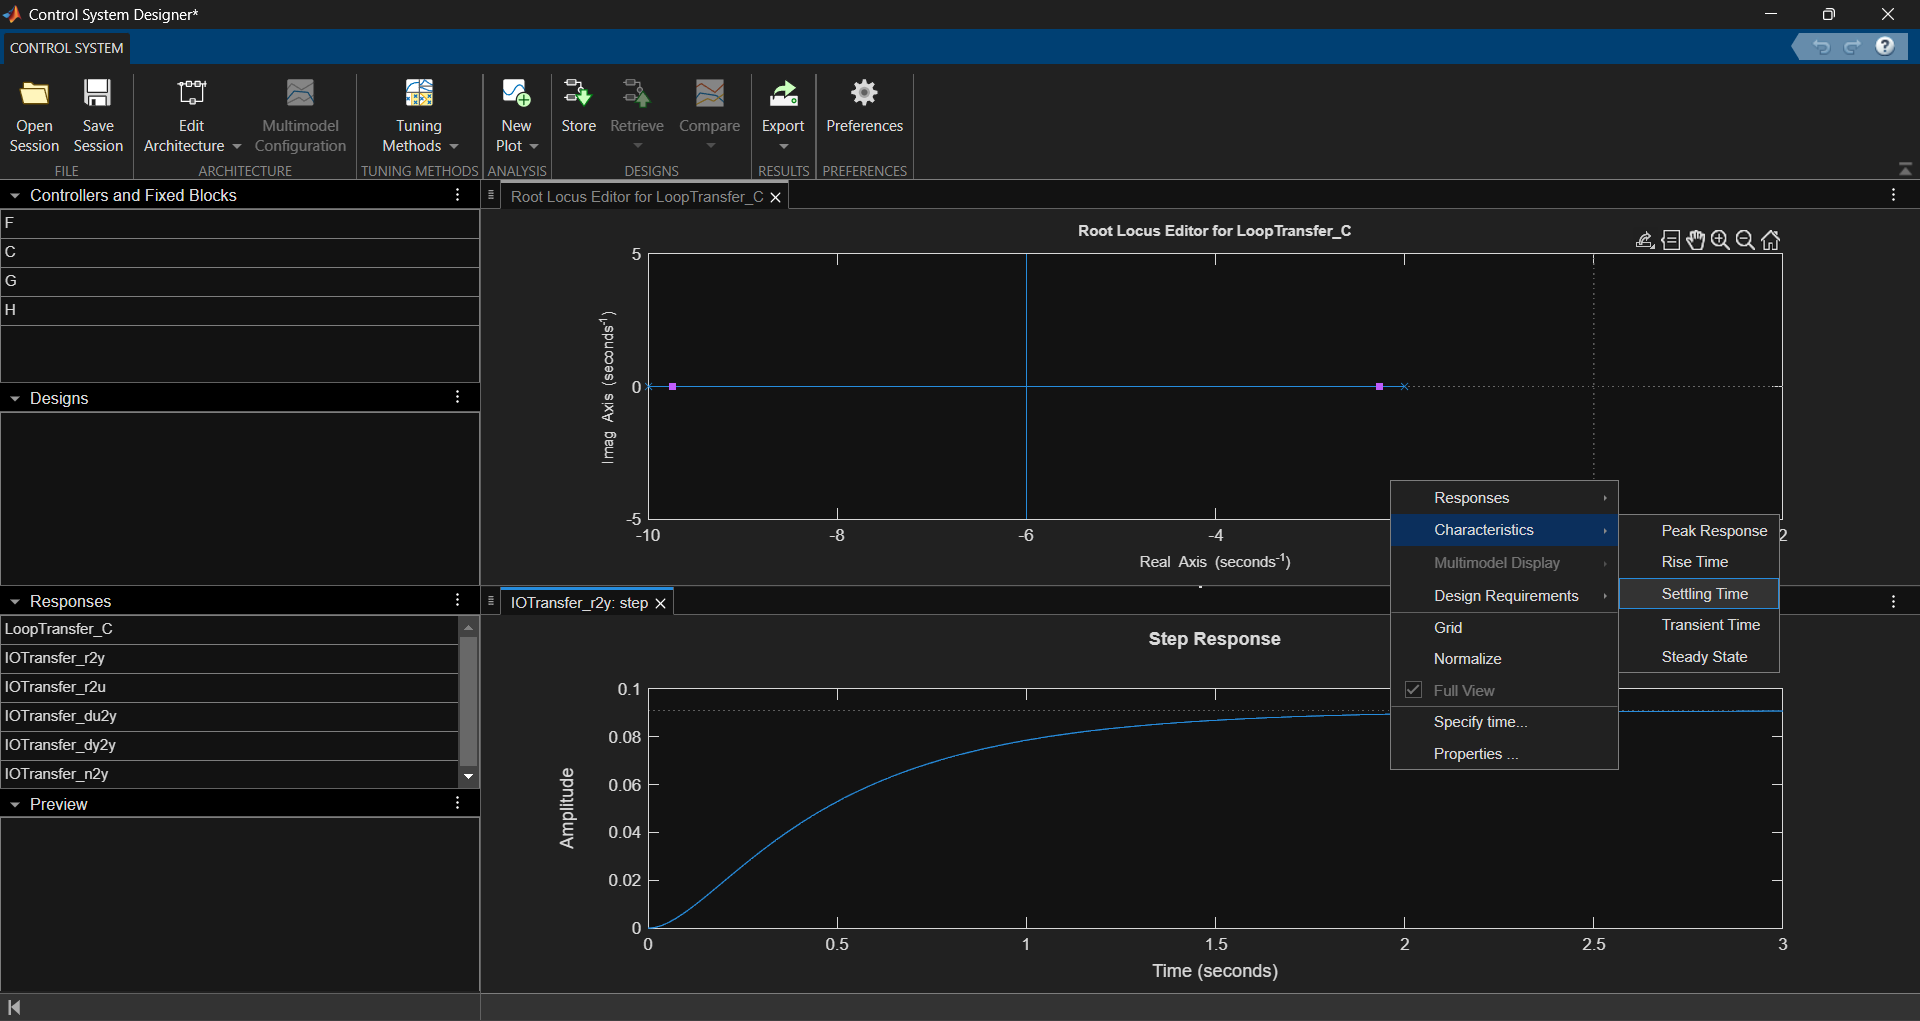

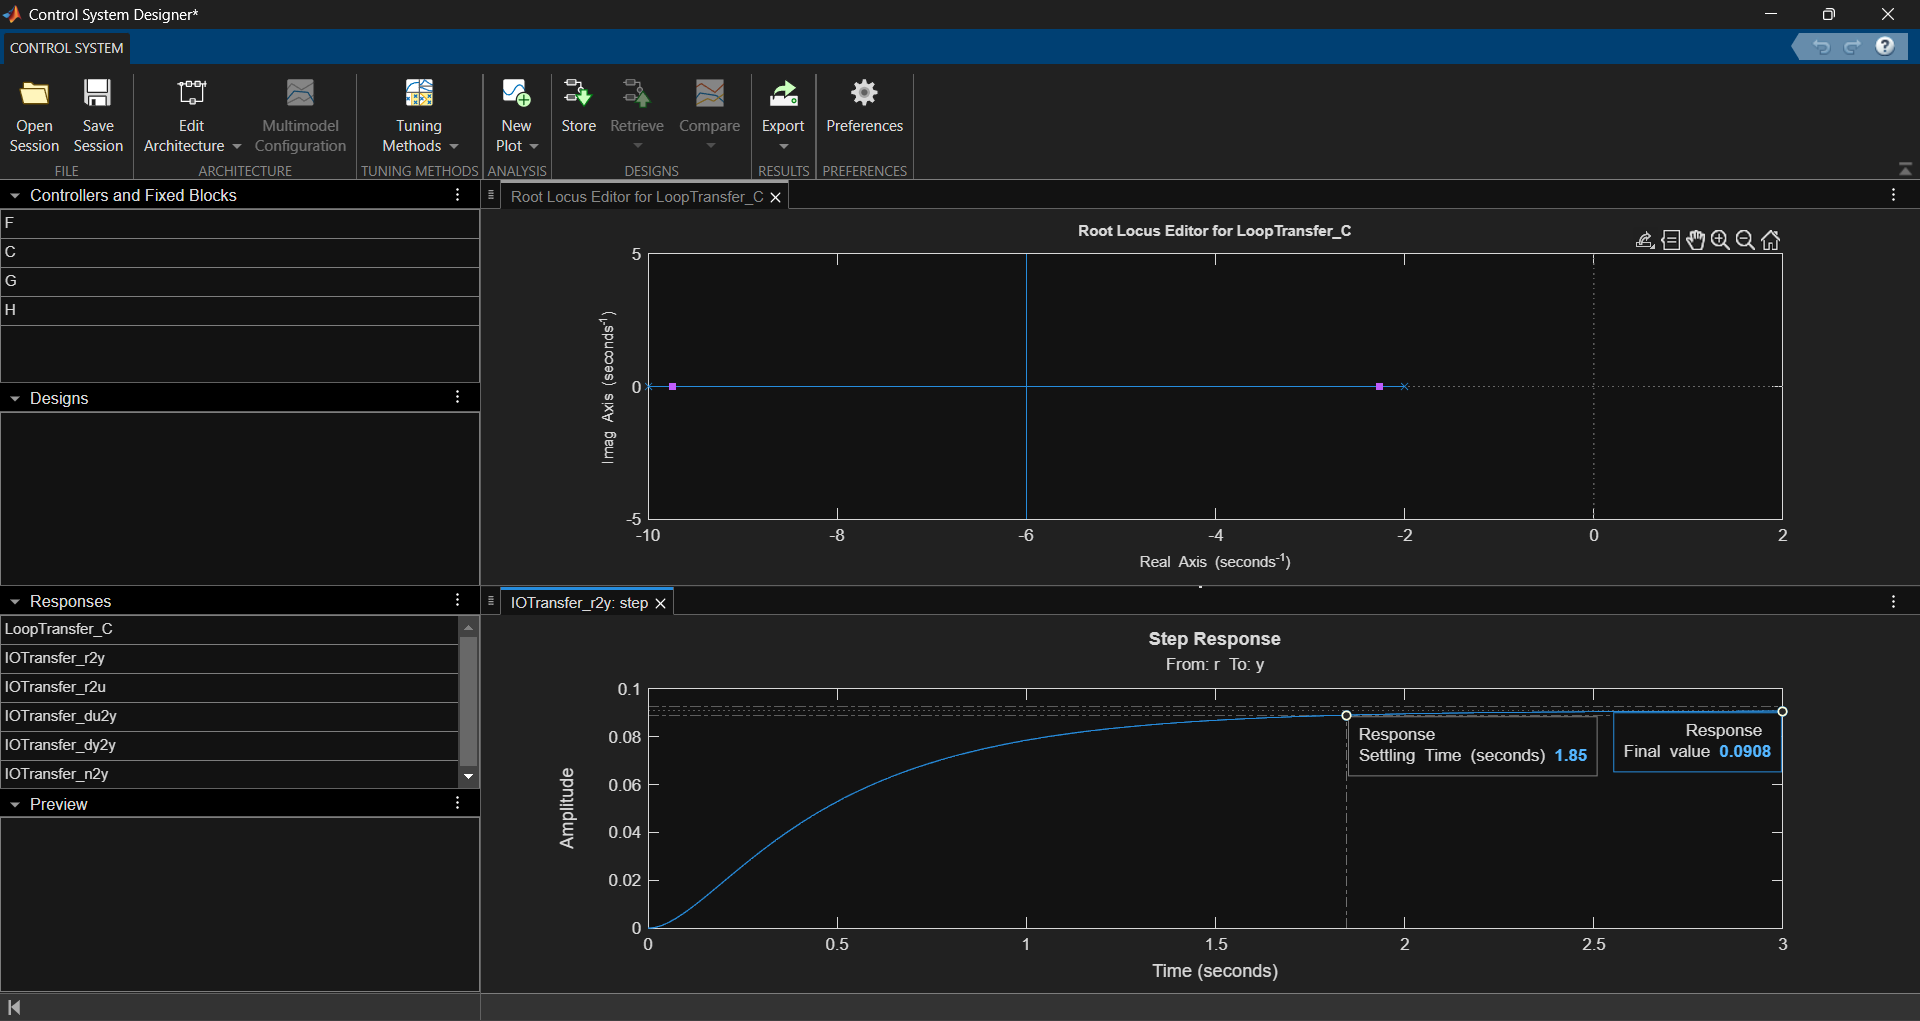

Right click on the `Root Locus Editor` and add `Design Requirements`.

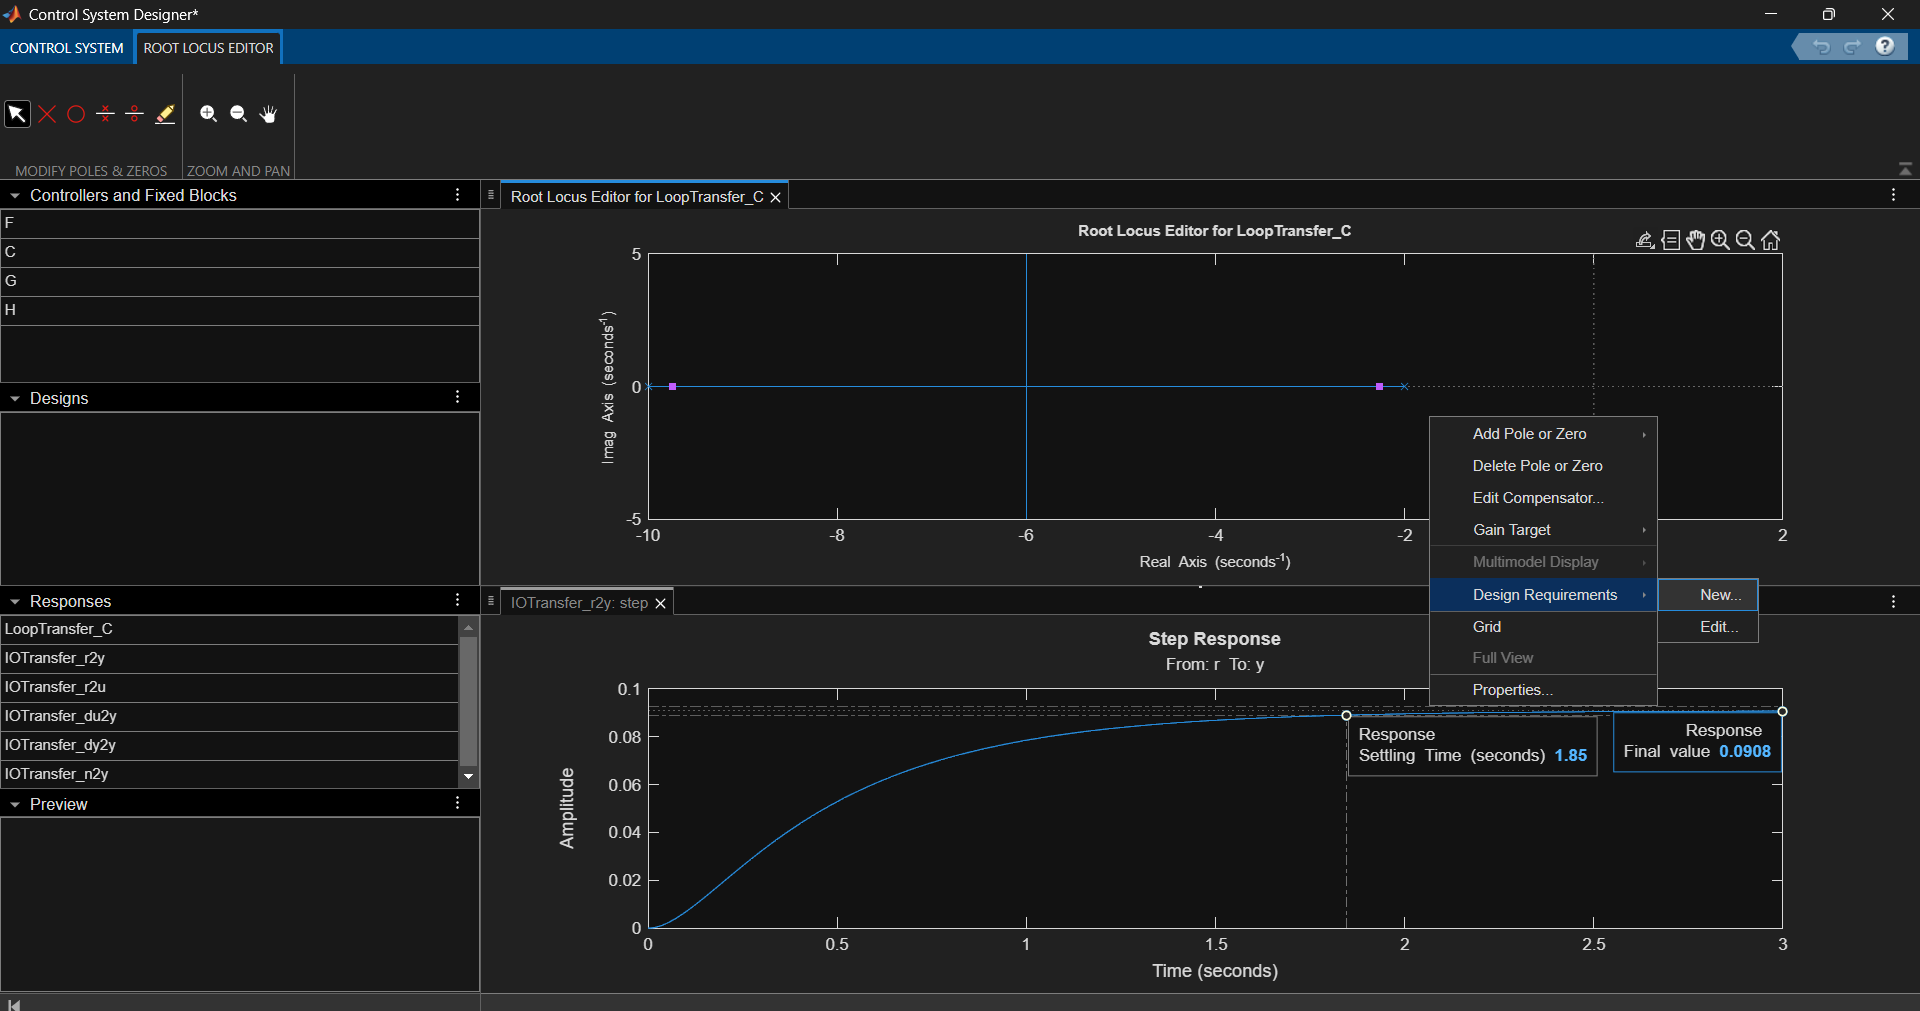

From the `Design requirement type` select `Settling time` and add 2 seconds.

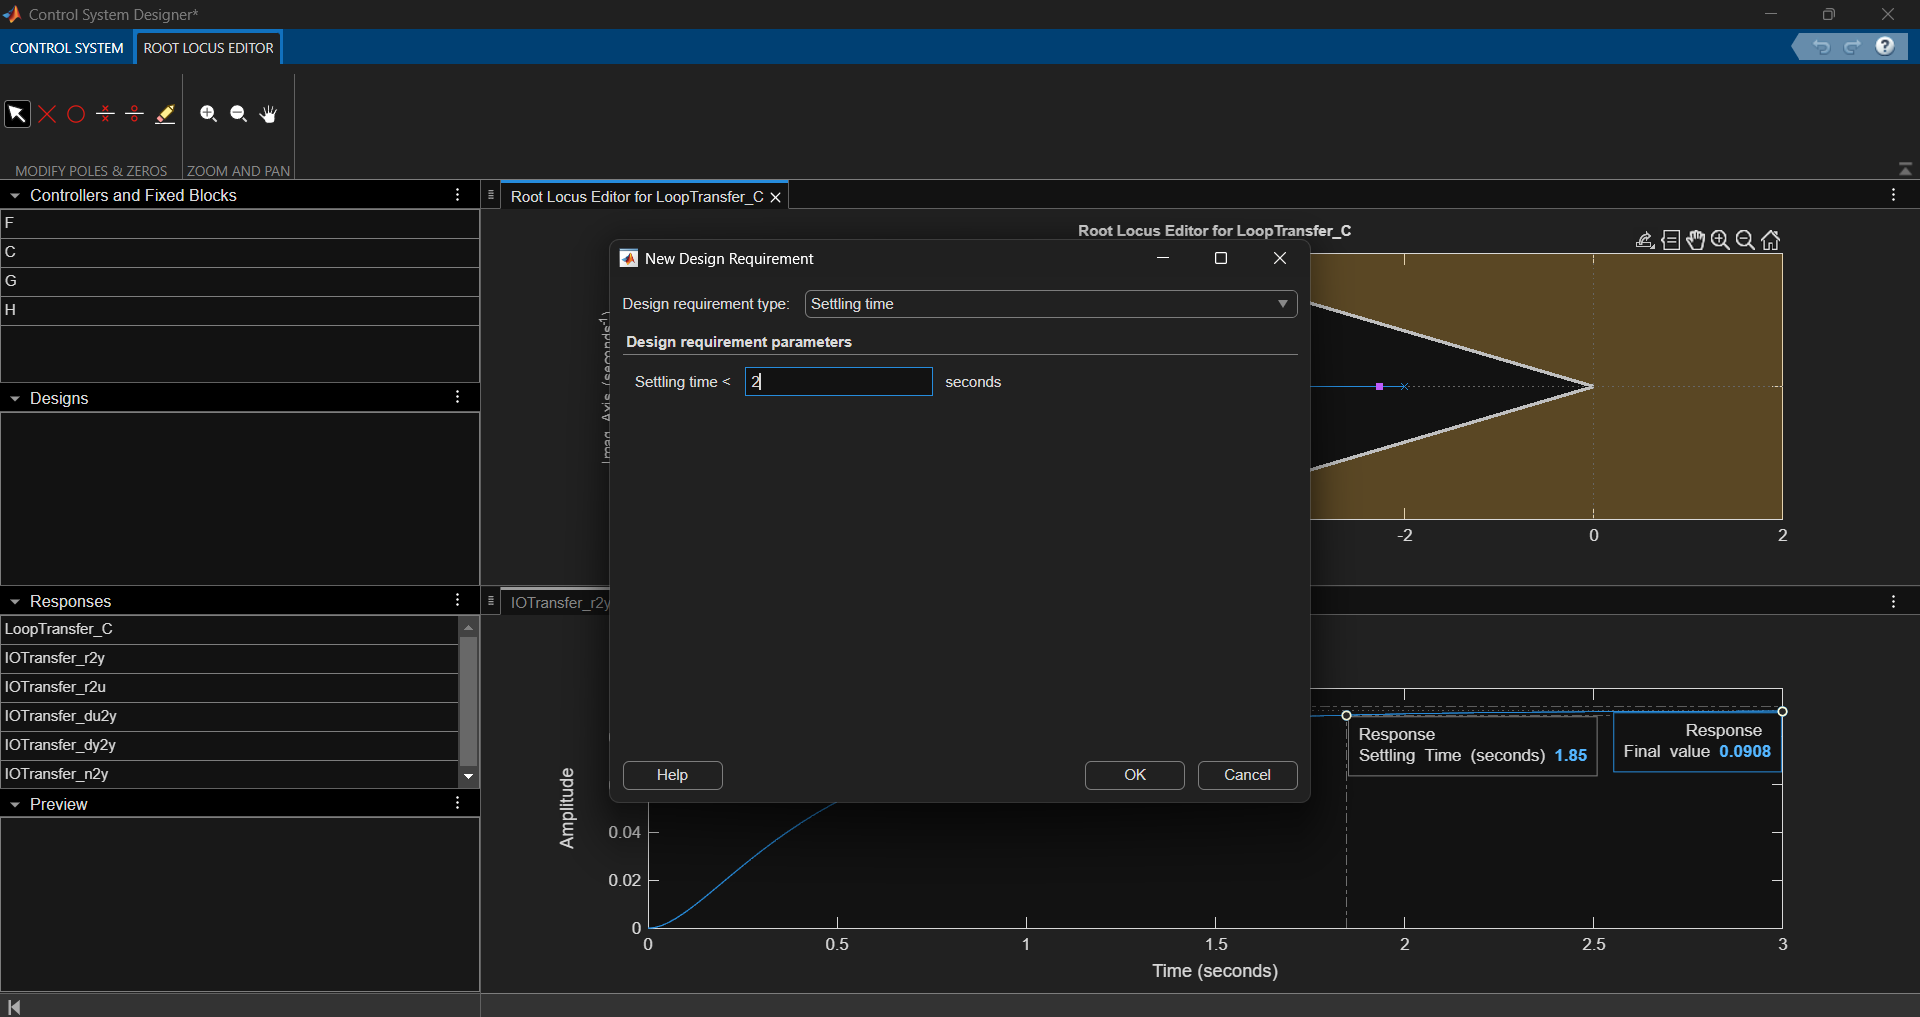

Add another `Design Requirement` -> From the `Design requirement type` select `Percent overshoot (%)` and add 5.

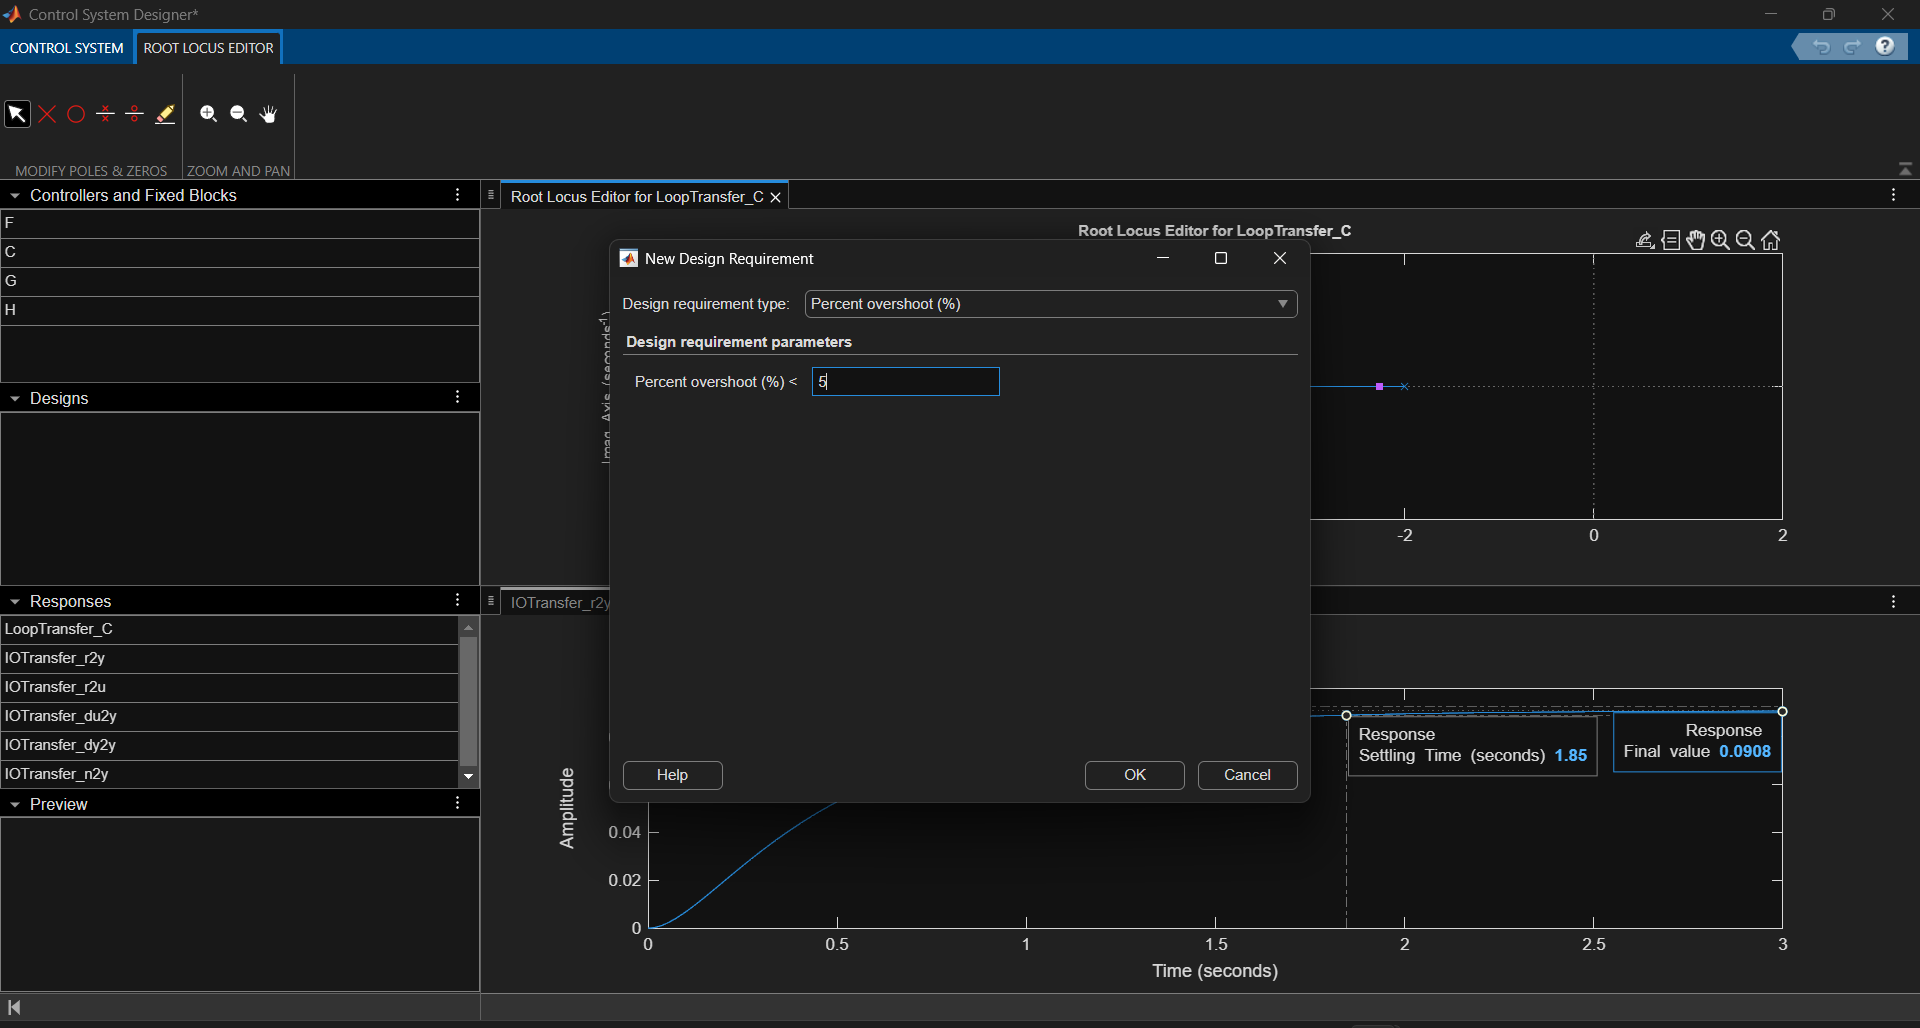

Your `Root Locus Editor` should look something like this:

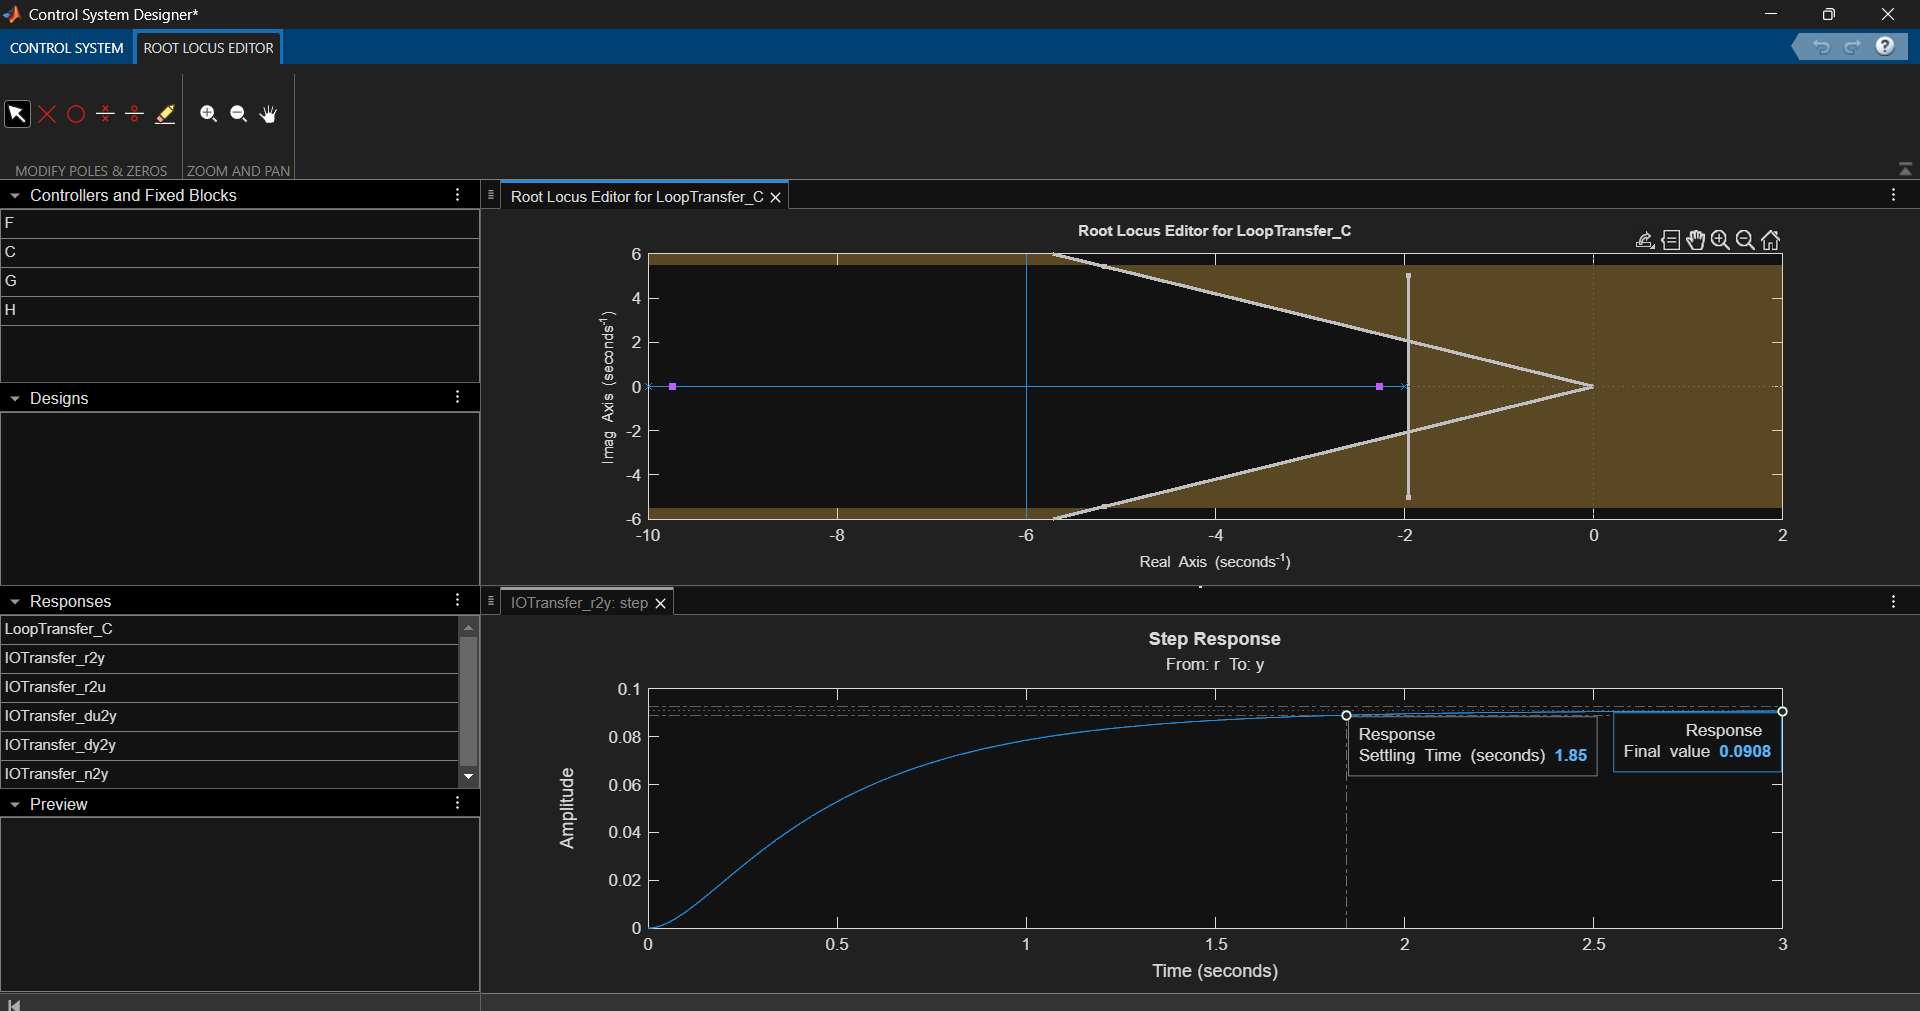

Now add a `real pole` and a `real zero`:

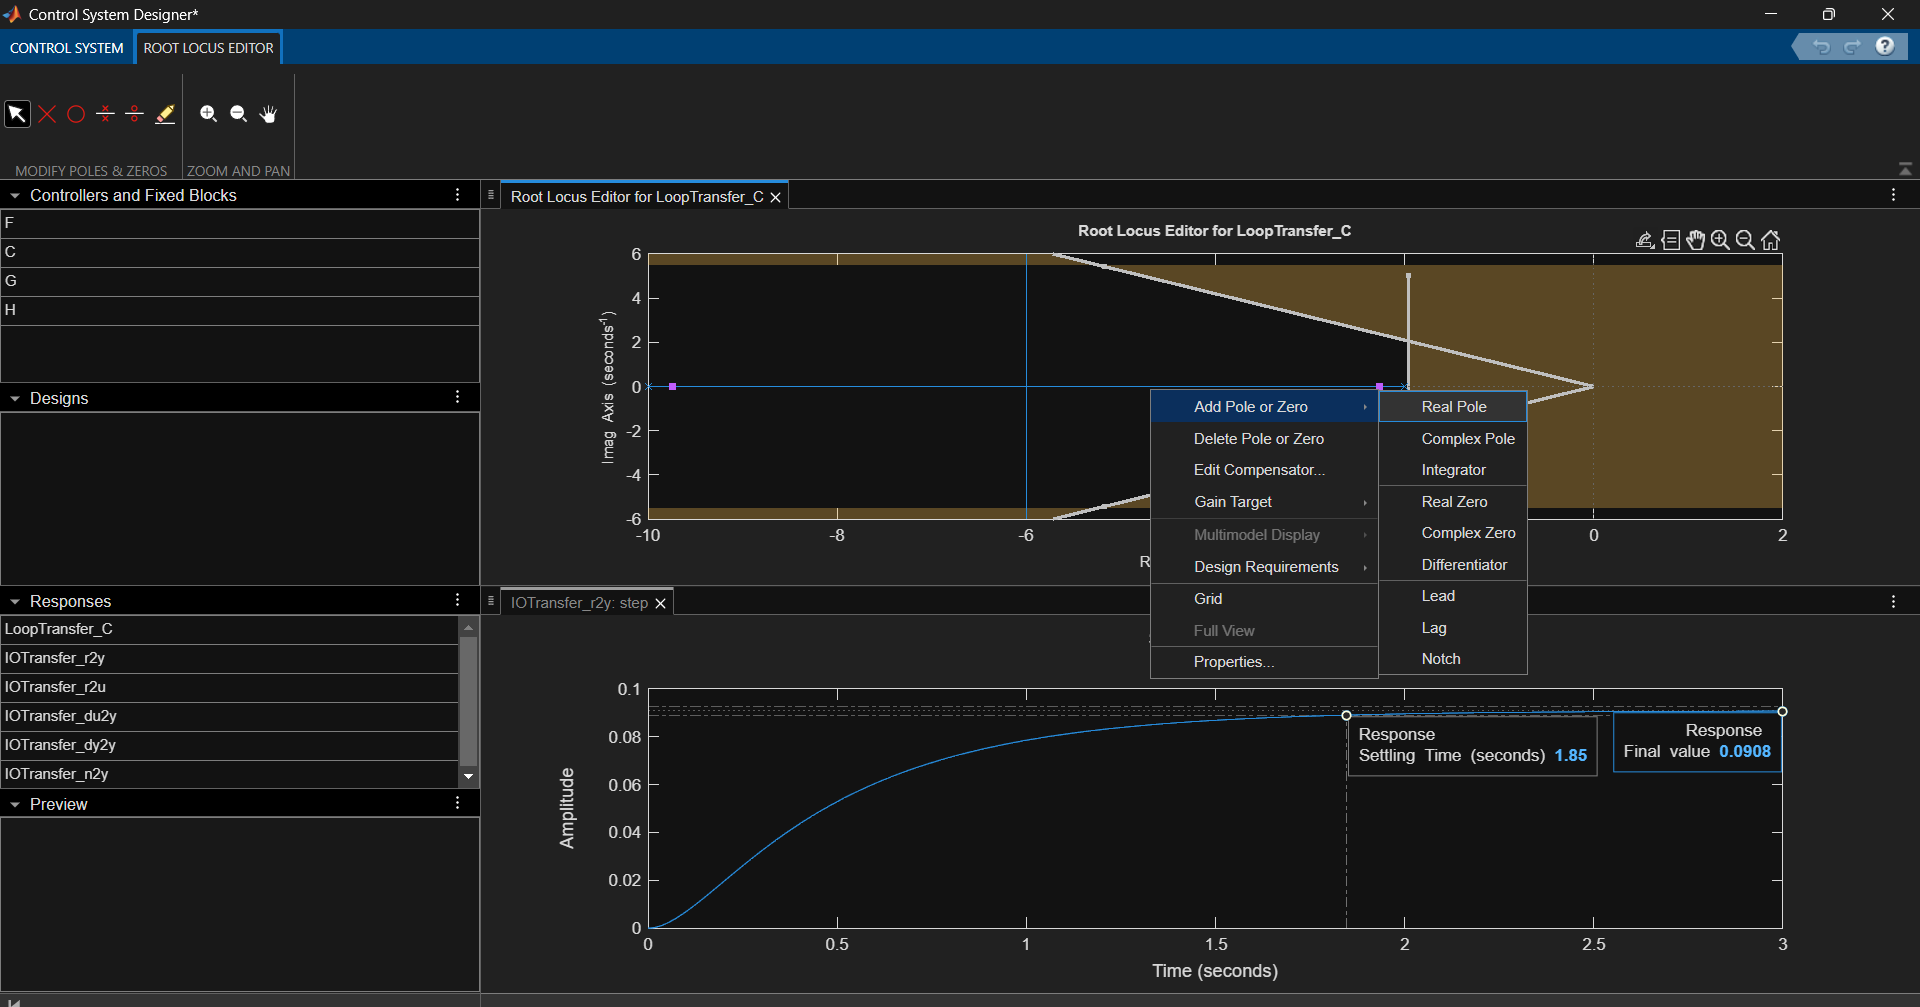

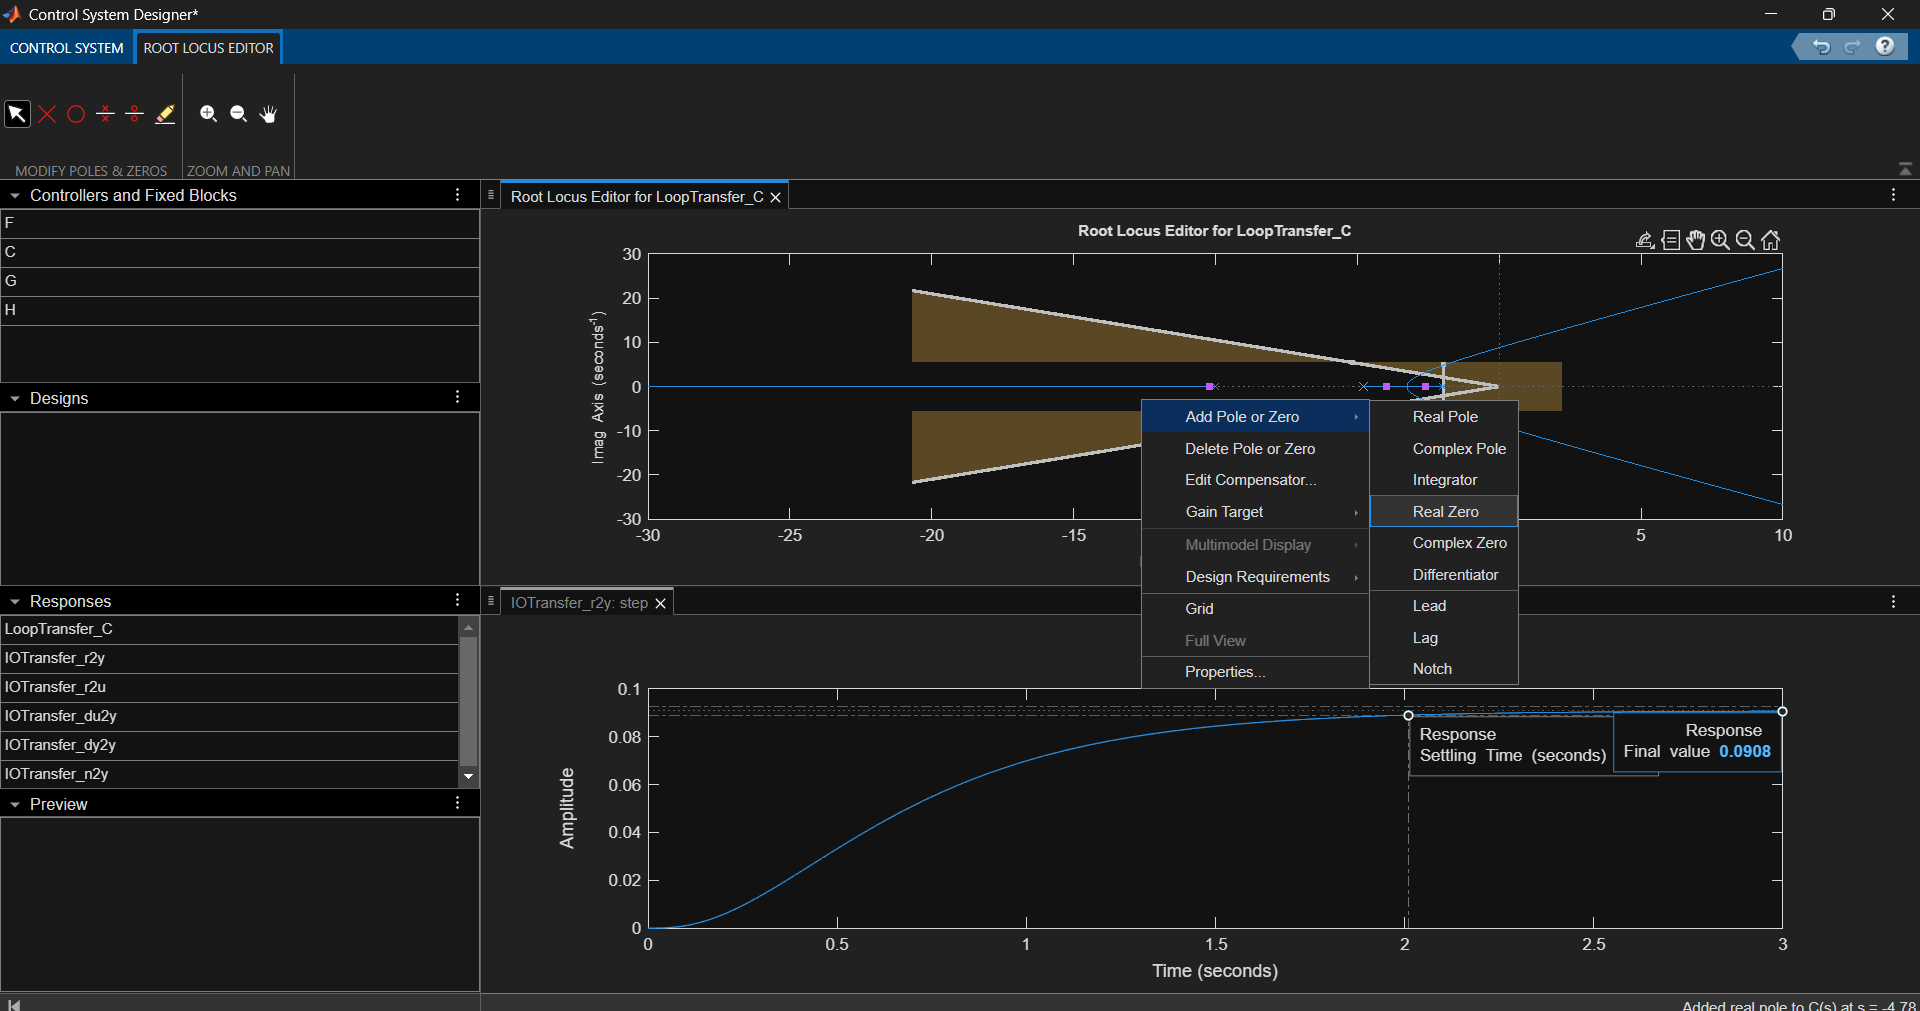

Right click on the figure and select `Edit Compensator` to change the locations of the pole (-0.01) and zero (-1).

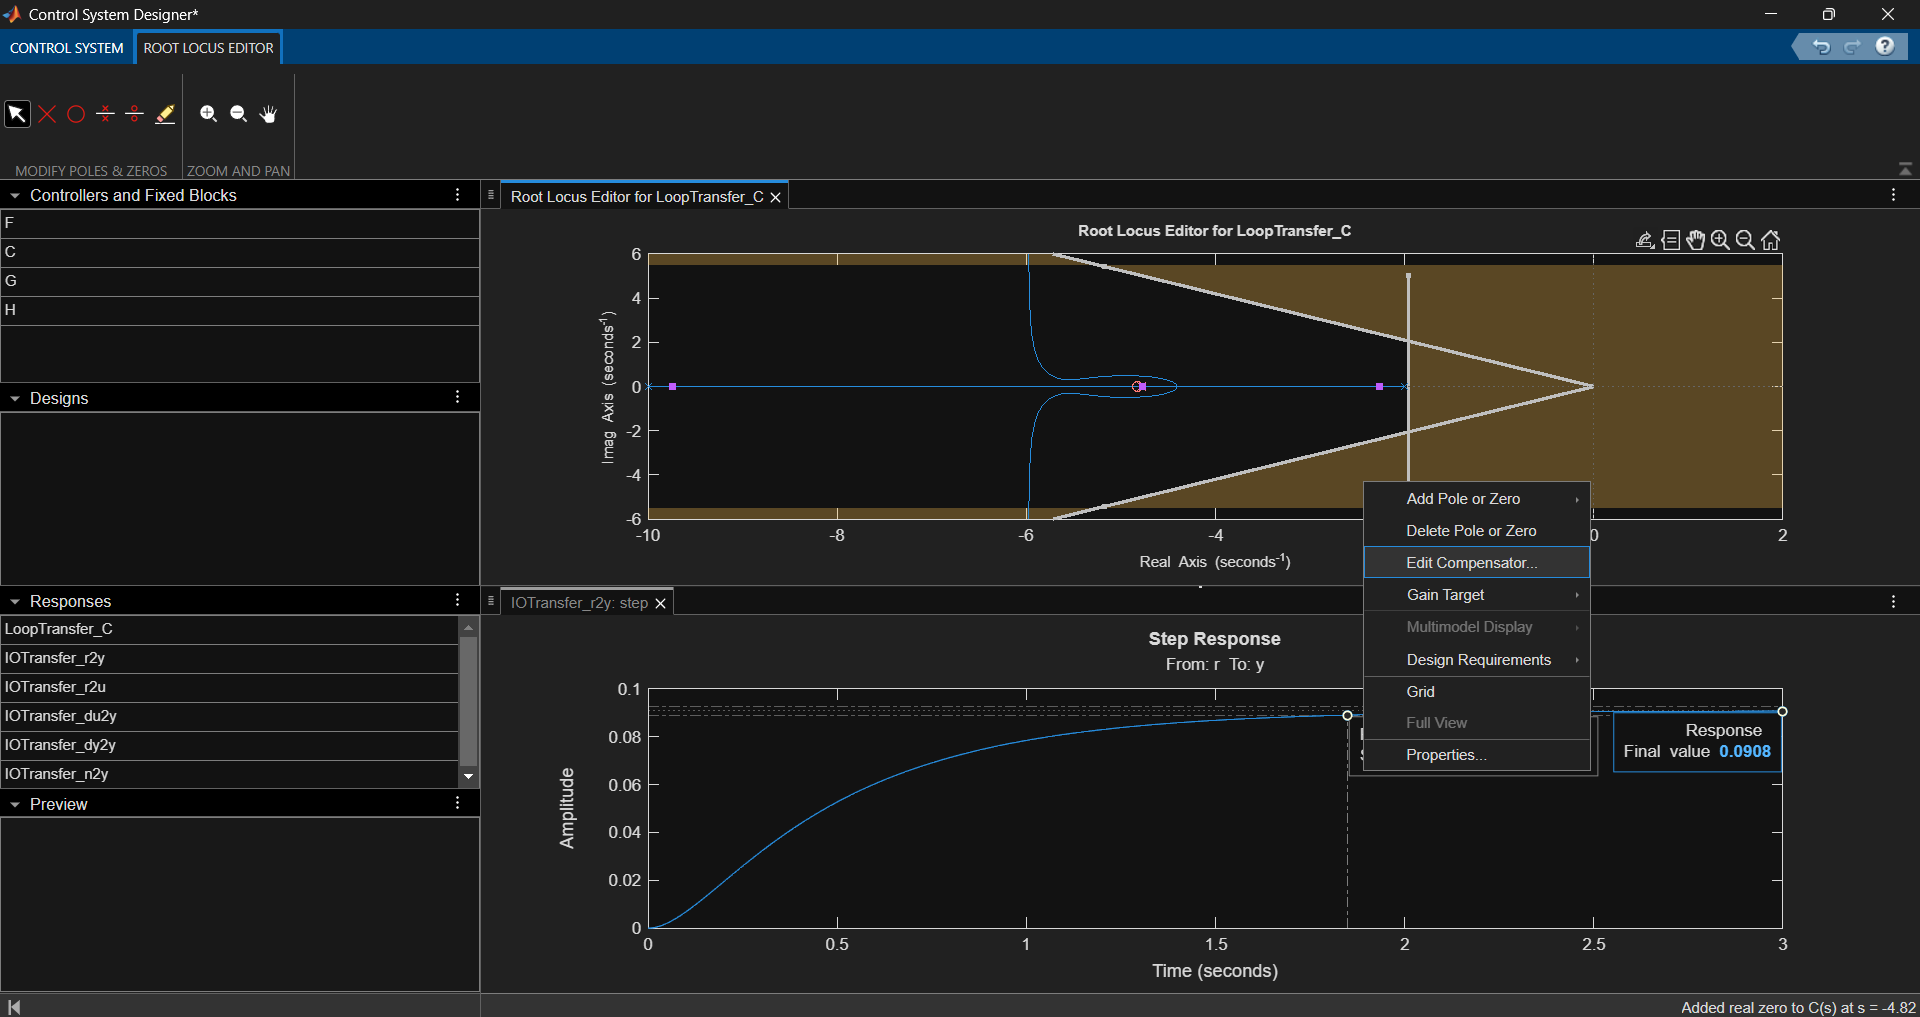

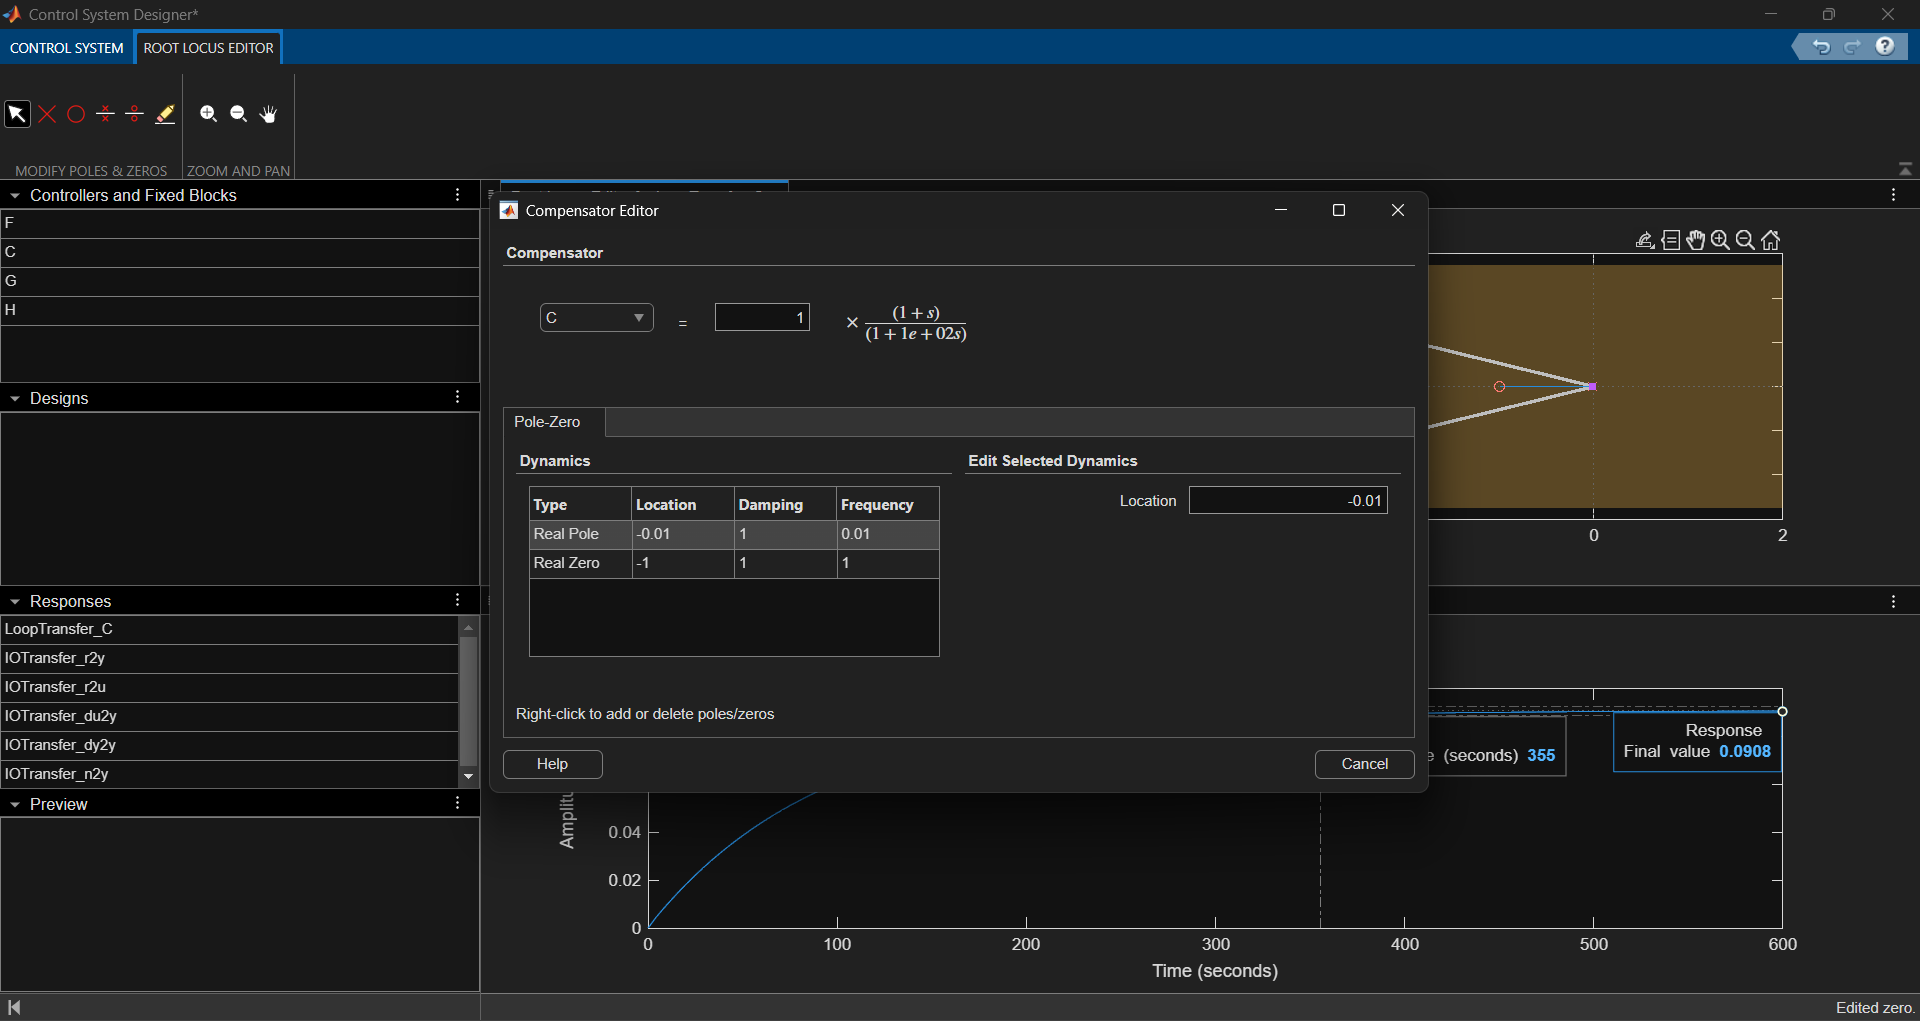

Now drag the poles to meet your design requirements. Alternatively, you can directly input value of Kc in the Compensator Editor:

After you edit your pole location, your `Root Locus Editor` can look something like this. Notice your overshoot is within 5%, settling time is below 2 seconds, and steady state value is very close to 1.

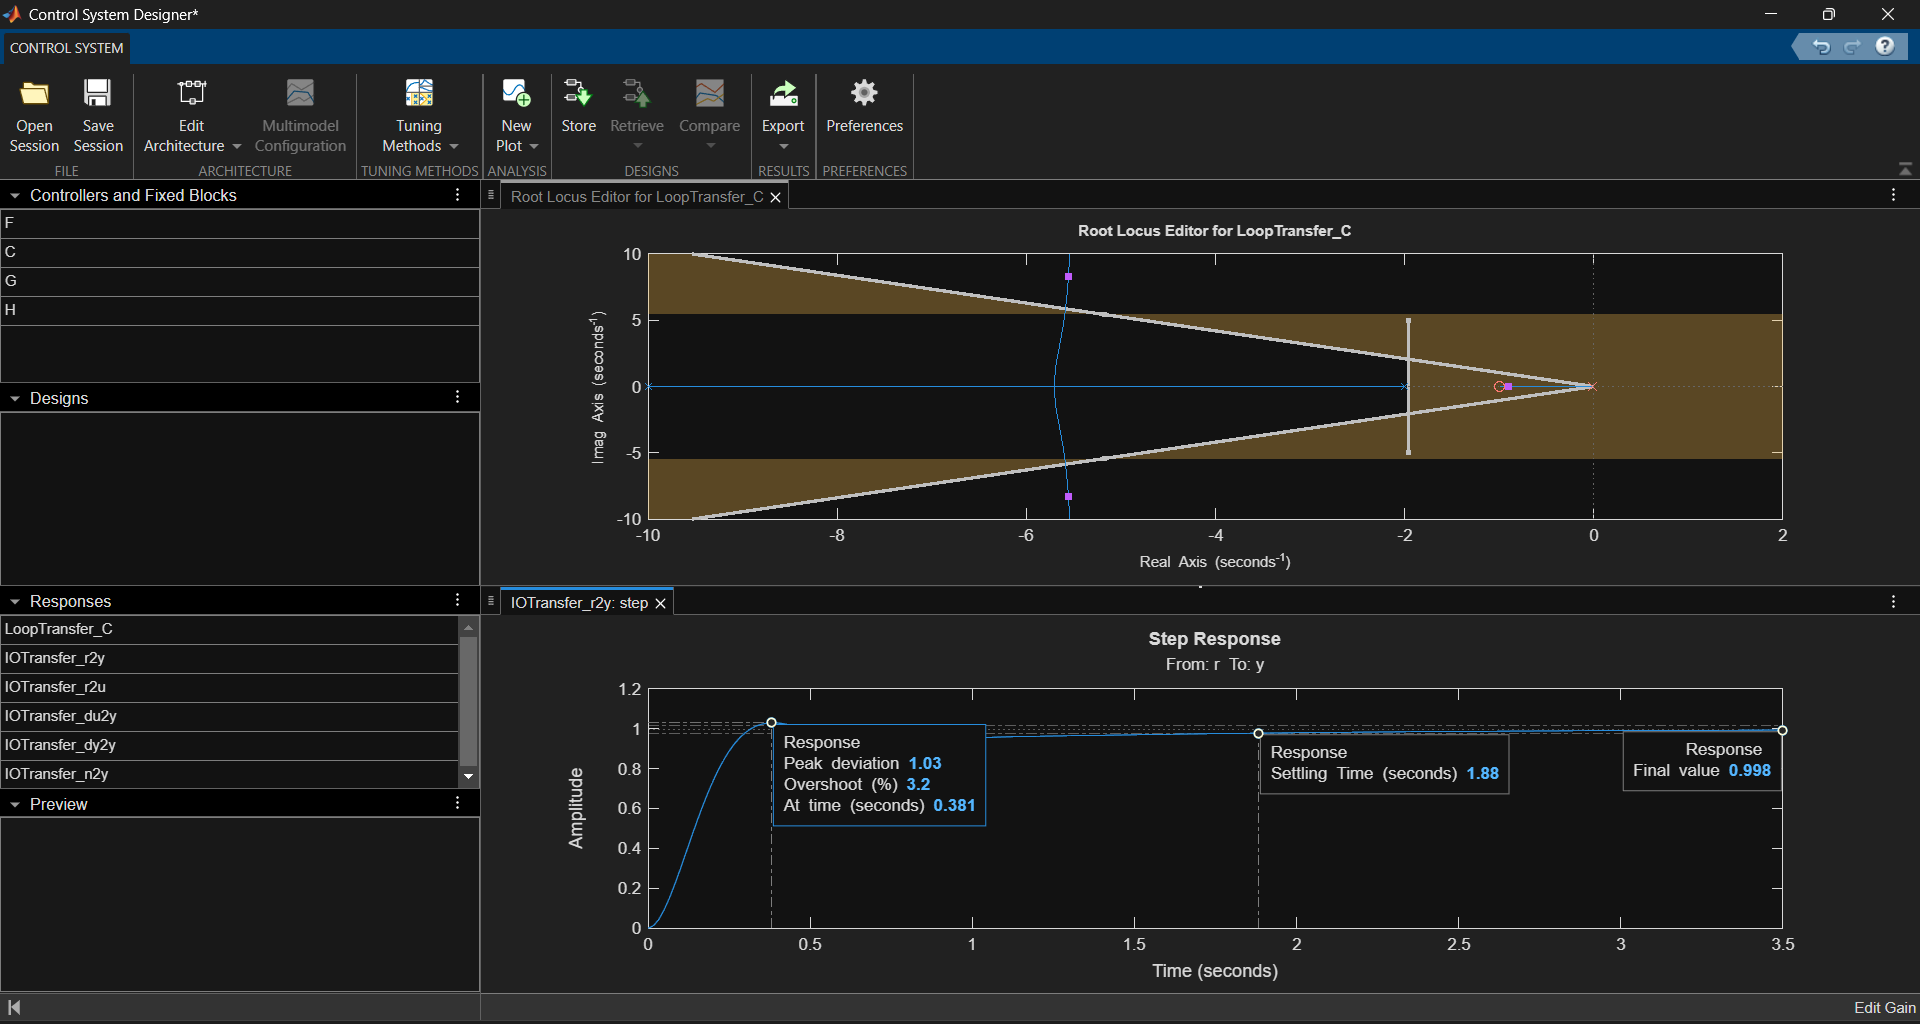

### Task 2

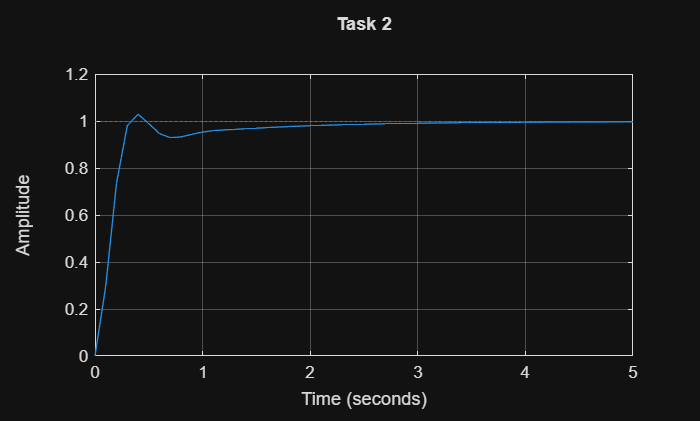

%% Task 2
Kc = 45;
compensator = Kc * (s+1)/(s+0.01);

% Define the close-loop system
sys_cl = feedback(compensator * P_motor, 1);

t = 0:0.1:5;

step(sys_cl,t);
title('Task 2');
grid on;

damp(sys_cl)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -9.01e-01                 1.00e+00       9.01e-01         1.11e+00    
 -5.55e+00 + 8.32e+00i     5.55e-01       1.00e+01         1.80e-01    
 -5.55e+00 - 8.32e+00i     5.55e-01       1.00e+01         1.80e-01    


### Task 3

Repeat Task 2 in Simulink and add screenshot below.